clear
clc
close all

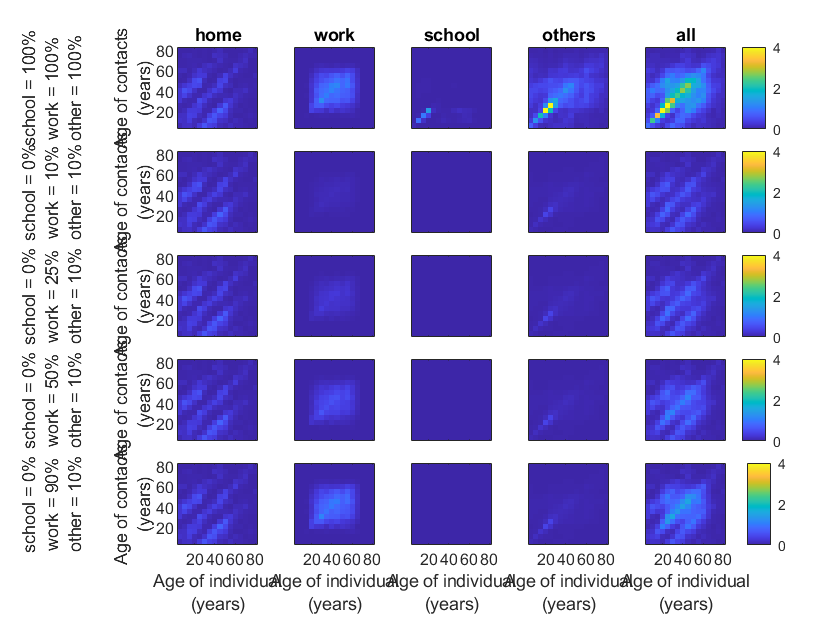


% sample age-location specific contact matrix
load("contacts_china.mat")

fn = fieldnames(contacts_china);
rows = 5;
cols = length(fn);
prop = [1, 0.1, 0.25, 0.5, 0.9];

Ms = nan(16, 16, rows, cols);


for row = 1:rows
    for col = 1:cols
        if row == 1
            Ms(:, :, row, col) = contacts_china.(fn{col})';
        else
            if col == 2
                Ms(:, :, row, col) = contacts_china.(fn{col})' * prop(row);
            elseif col == 3
                Ms(:, :, row, col) = contacts_china.(fn{col})' * row == 1;
            elseif col == 4
                if row == 1
                    Ms(:, :, row, col) = contacts_china.(fn{col})';
                else
                    Ms(:, :, row, col) = contacts_china.(fn{col})' * 0.1;
                end
            elseif col == 5
                Ms(:, :, row, col) = sum(Ms(:, :, row, 1:4), 4);
            else
                Ms(:, :, row, col) = contacts_china.(fn{col})';
            end
        end
        
    end
end

names = fieldnames(contacts_china);

figure
tiledlayout(rows, cols)
for row = 1:rows
    for col = 1:cols
        nexttile
        imagesc(Ms(:, :, row, col));
        axis square
        caxis([0, 4])
        set(gca, "YDir", "normal");
        xticks([0:4:16]);
        xticklabels([0:20:80]);
        yticks([0:4:16]);
        yticklabels([0:20:80]);
        xlabel(["Age of individual", "(years)"])
        if row == 1
            ylabel(["school = 100%", "work = 100%", "other = 100%", "", "Age of contacts", "(years)"])
        elseif row == 2
            ylabel(["school = 0%", "work = 10%", "other = 10%", "", "Age of contacts", "(years)"])
        elseif row == 3
            ylabel(["school = 0%", "work = 25%", "other = 10%", "", "Age of contacts", "(years)"])
        elseif row == 4
            ylabel(["school = 0%", "work = 50%", "other = 10%", "", "Age of contacts", "(years)"])
        elseif row == 5
            ylabel(["school = 0%", "work = 90%", "other = 10%", "", "Age of contacts", "(years)"])
        end
%         set(gca, "FontSize", 12)
        
        if row == 1
            title(names(col))
        end
        if col ~= 1
            set(gca, "YTickLabel", [], "YLabel", [])
        end
        if row ~= rows
            set(gca, "XTickLabel", [], "XLabel", [])
        end
        if col == cols
            colorbar eastoutside 
        end
    end
end